# 1229第十七次上机实验

**1.** x = [1 2 5 4 8]; y = [x;1:5]，绘制一个堆叠的水平条形图

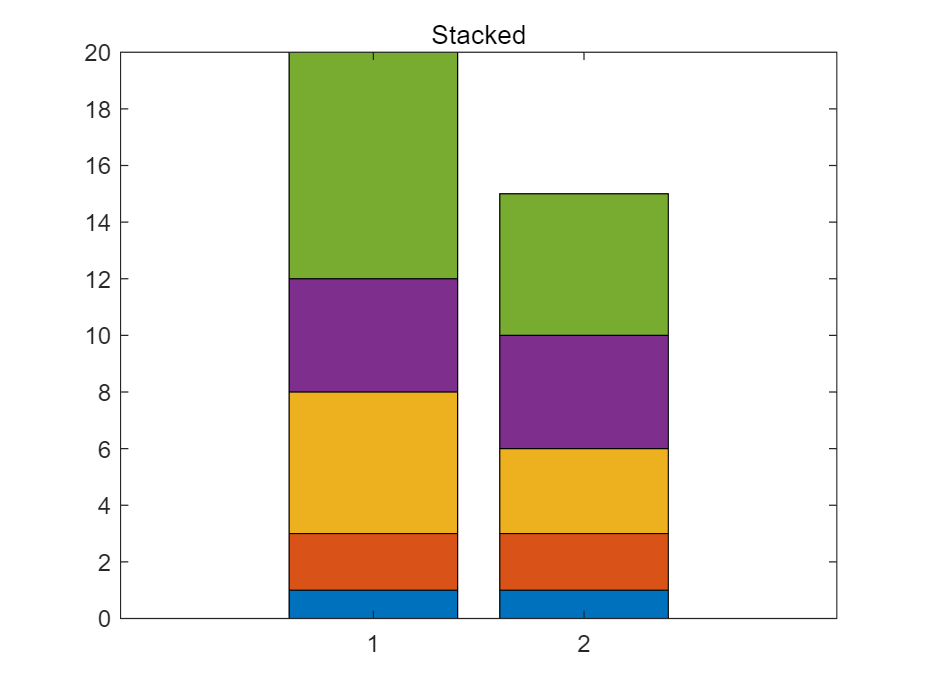

close all;
x = [1,2,5,4,8];
y = [x;1:5];
bar(y,'stacked');
title('Stacked');

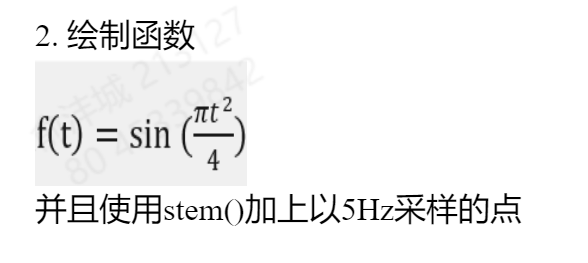

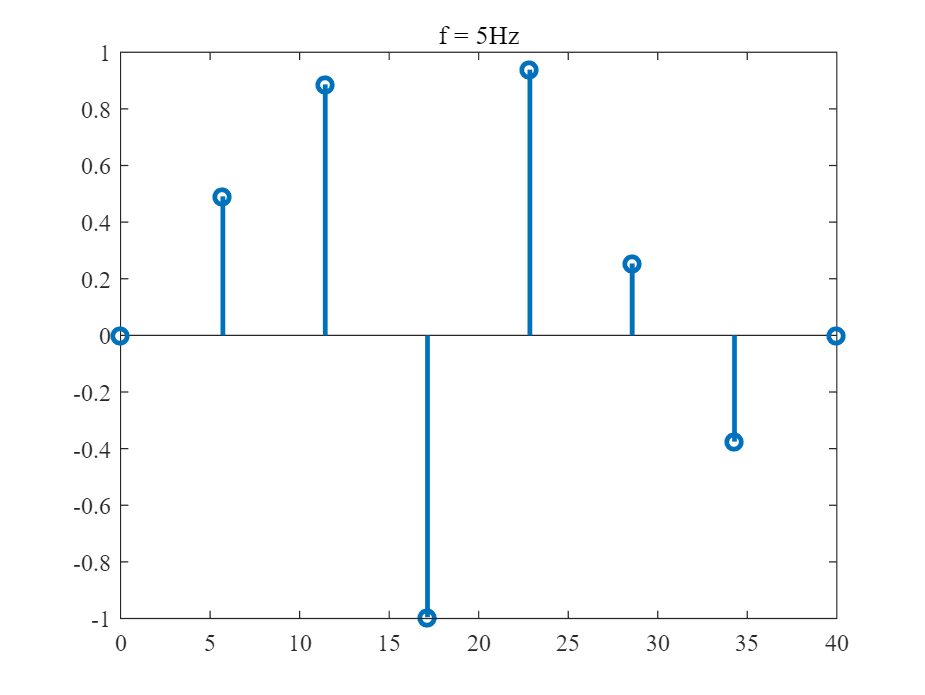

close all;
x = linspace(0,40,8);
y = sin(pi*(x.^2)/4);

stem(x,y,"LineWidth",2);
title('f = 5Hz');
set(gca,'FontName','Times New Roman');

`3.``创建一个自定义绿色图谱，使得`x = [1:10; 3:12; 5:14]; imagesc(x); `的输出如下图所示。`

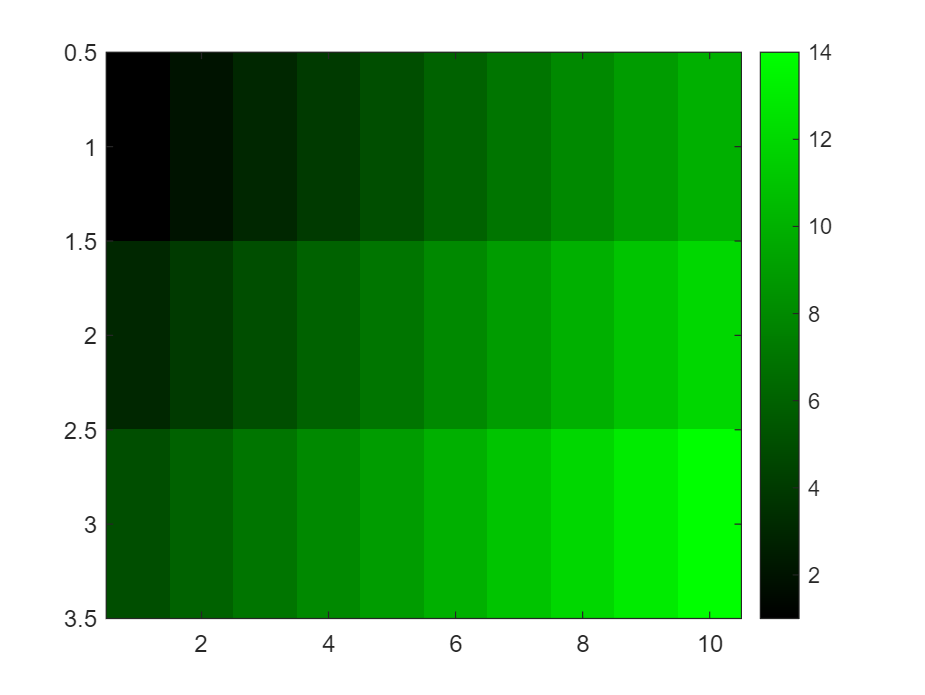

map = [zeros(1,255);linspace(0,1,255);zeros(1,255)];
x = [1:10; 3:12; 5:14];
imagesc(x);
colormap(map');
colorbar;

**4.** x = 1:0.1:3; y = 1:0.1:5; [X,Y] = meshgrid(x,y); Z = X.^2 + Y.^2; surf(X, Y, Z); `使用`colormap`重新绘制表面`

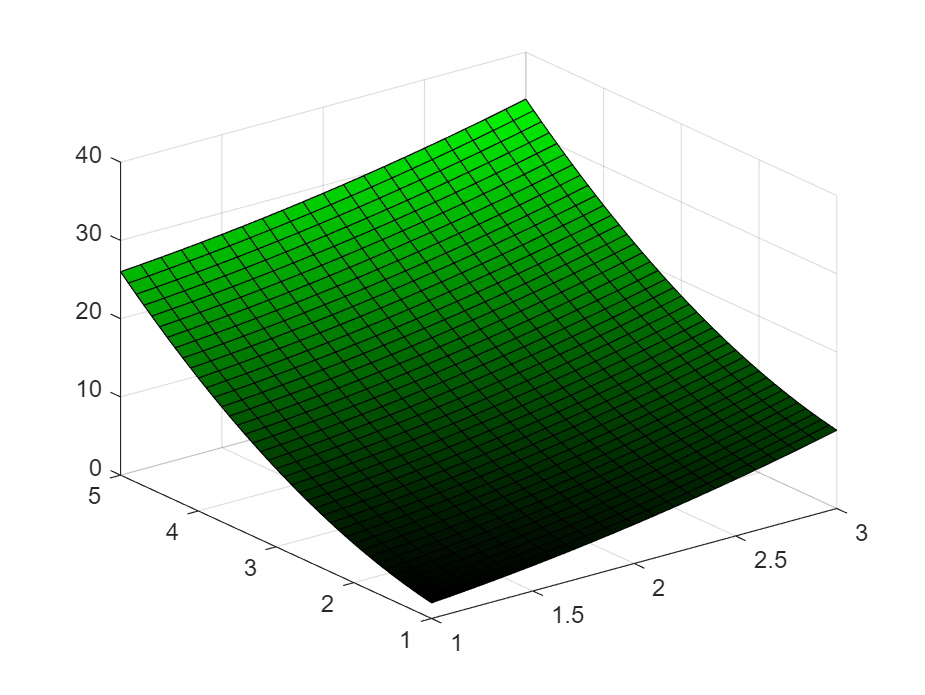

close all;

x = 1:0.1:3; 
y = 1:0.1:5; 
[X,Y] = meshgrid(x,y); 
Z = X.^2 + Y.^2; 
surf(X, Y, Z);
map = [zeros(1,255);linspace(0,1,255);zeros(1,255)];
colormap(map');

**5.  **A, B, C`三个城市上半年每个月的国民生产总值如图所示，试分析图示数据并自定义数值，画出三城市上半年生产总值饼图。`

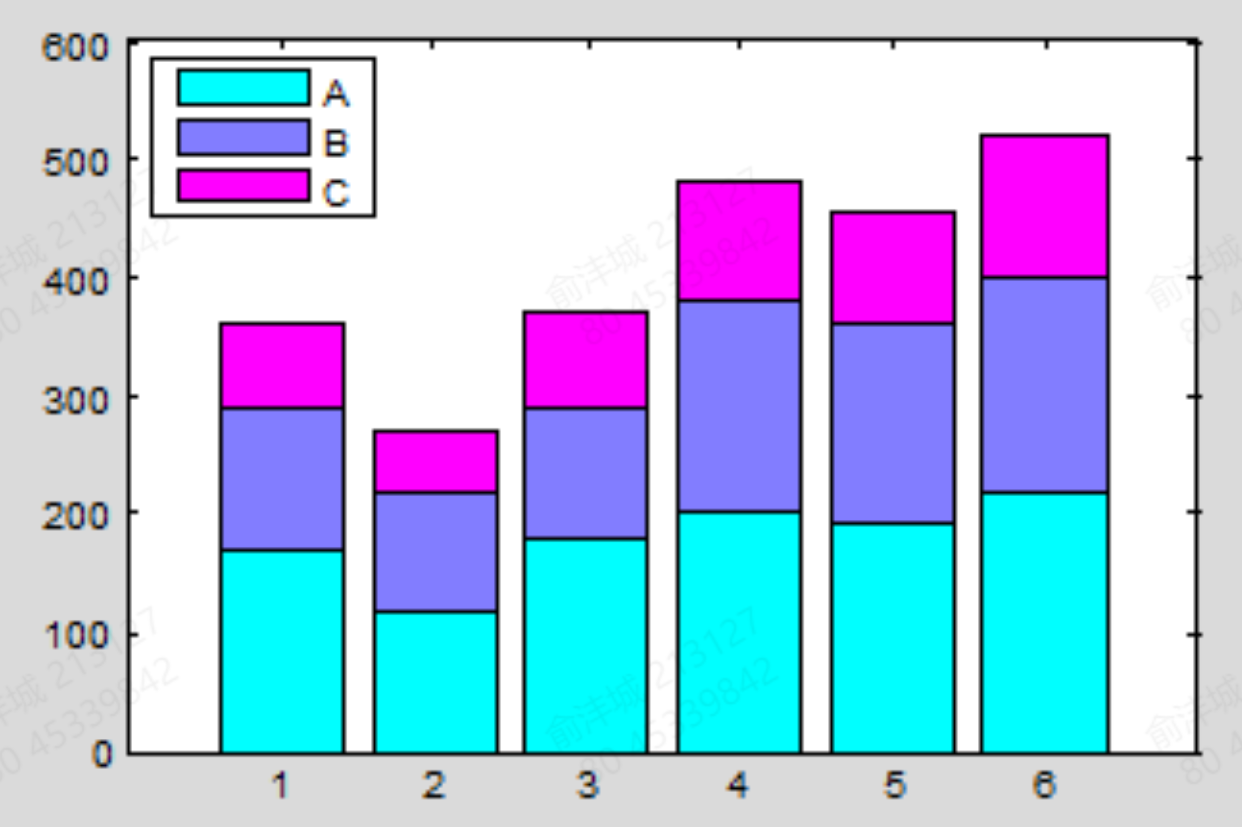

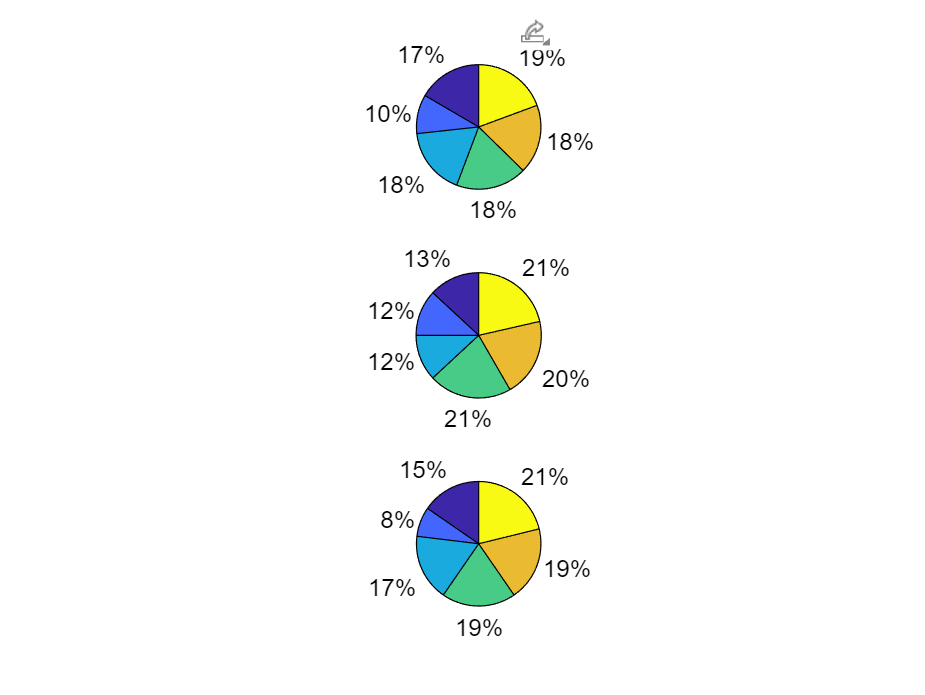

clear all;close all;
A = [180,110,190,200,195,210];
B = [110,100,100,180,170,180];
C = [80,40,90,100,100,110];
subplot(3,1,1);
title('A');
pie(A);
subplot(3,1,2);
title('B');
pie(B);
subplot(3,1,3);
title('C');
pie(C);

**6.** `绘制`

`在`x, y∈[-3, 3]`的三维透视网格曲面。`

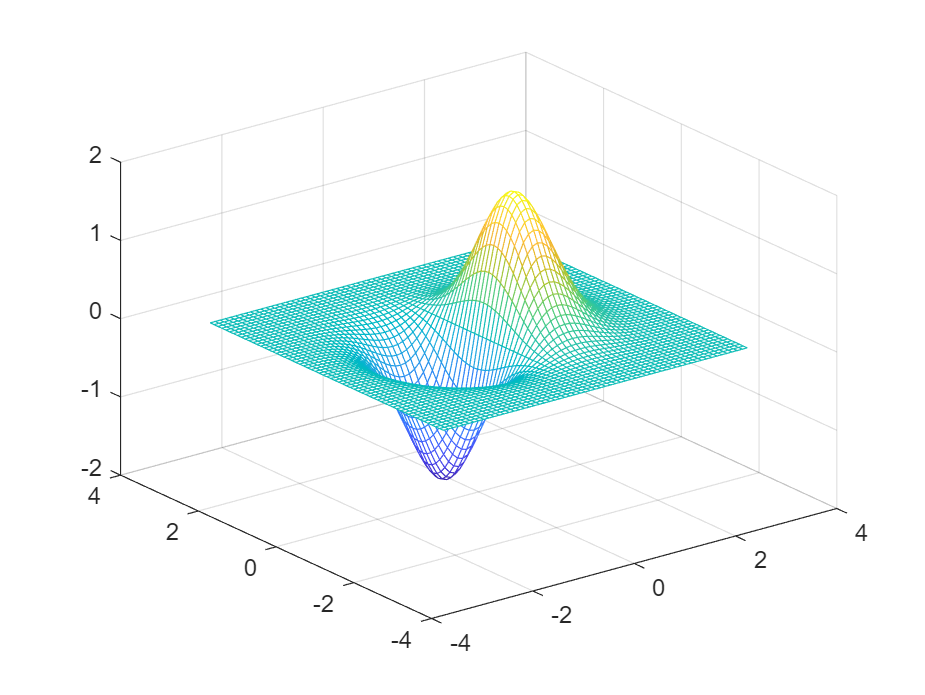

close all;clear all;
x = -3:0.1:3;
y = -3:0.1:3;
[X,Y] = meshgrid(x,y);
Z = 4.*X.*exp(-X.^2-Y.^2);
mesh(X,Y,Z);
set(gca,'color','none');